Addpath

clear;clc;
close all
addpath("PandaDyn\")
addpath("Dynamics\")
addpath("..\ReadYAML\")
addpath("..\")
config=ReadYaml("Configuration\FrankaEmikaPanda.yaml");

## Configurations

Critical $t_s$ is $0.00787$ ~ $0.00788$ second.

SolverOpt

SolverOpt.initial_condition=config.StateInitial';
SolverOpt.end_time=config.SimulationTime;
% SolverOpt.sampling_time=config.ts;
SolverOpt.sampling_time=0.00788;
SolverOpt.ratio=config.ratio;
SolverOpt.ode_setting=odeset('RelTol', config.ODE_RelTol, ...
    'AbsTol', config.ODE_AbsTol);

Other parameters

TargetAngle=config.TargetAngle';
Kp=diag(config.Kp);
Kd=diag(config.Kd);

Solver Option

option=odeset('RelTol', 1e-12, 'AbsTol', 1e-12);

### Continuous Time Case

History Matrix

TorqueHistoryContinuous=zeros(7,round(SolverOpt.end_time/config.dt)+1);

Simulation

tic
[t,State]=ode45(@(t,State)ODE(t,State,PDTorque(Kp,Kd,State,TargetAngle)), ...
    0:config.dt:SolverOpt.end_time,SolverOpt.initial_condition,option);
command="data.continuous.duration=t;";
command=command+"data.continuous.state_history=State';";
eval(command);
for i=1:round(SolverOpt.end_time/config.dt)+1
    TorqueHistoryContinuous(:,i)=PDTorque(Kp,Kd,data.continuous.state_history(:,i),TargetAngle);
end
command="data.continuous.input_history=TorqueHistoryContinuous;";
eval(command);
toc

历时 3.381354 秒。


## Digital Feedback Control Case

System ODE and Input Function

SysODE=@(t,State,Torque)ODE(t,State,Torque);
InputFun=@(state)PDTorque(Kp,Kd,state,TargetAngle);

Simulation

sol=SampledControlSolver(SysODE,InputFun,SolverOpt);

历时 32.550285 秒。


data.digital.ts=sol.ts;
data.digital.duration=sol.duration;
data.digital.state_history=sol.state_history;
data.digital.input_history=sol.input_history;
command="data.digital.state_history_interp=[";
for i=1:14
    command=command+"interp1(data.digital.duration,"+...
        "data.digital.state_history("+num2str(i)+",:),"+...
        "data.continuous.duration,'spline','extrap')';";
end
command=command+"];";
eval(command);
command="data.digital.input_history_interp=[";
for i=1:7
    command=command+"interp1(data.digital.duration,"+...
        "data.digital.input_history("+num2str(i)+",:),"+...
        "data.continuous.duration,'spline','extrap')';";
end
command=command+"];";
eval(command);

### Delay Control Case

Controller

tic
Controller=@(State)PDTorque(Kp,Kd,State,TargetAngle);

History Solution

history=@(t)get_HistorySolution(t,SolverOpt.initial_condition);

Simulation

option=ddeset('RelTol', 1e-12, 'AbsTol', 1e-12,"InitialStep",config.dt, ...
    "MaxStep",1.5*config.dt);
sol=dde23(@(t,State,StateDelayed)DDE(t,State,StateDelayed,Controller), ...
    1.5*data.digital.ts,history,data.continuous.duration,option);

Show Time Steps

disp("Simulation time steps: "+num2str(length(sol.x)))

Simulation time steps: 68137


disp("Visualization time steps: "+num2str(length(data.continuous.duration)))

Visualization time steps: 1001


Store data

data.delay.delay_time=1.5*data.digital.ts;
data.delay.duration=sol.x;
data.delay.state_history=sol.y;
command="data.delay.state_history_interp=[";
for i=1:14
    command=command+"interp1(data.delay.duration,"+...
        "data.delay.state_history("+num2str(i)+",:),"+...
        "data.continuous.duration,'spline','extrap')';";
end
command=command+"];";
eval(command);
data.delay.input_history_interp=zeros(7,length(data.continuous.duration));
for i=1:length(data.continuous.duration)
    index=round((data.continuous.duration(i)-data.delay.delay_time)/config.dt);
    if index<=0
        delay_state=SolverOpt.initial_condition;
    else
        delay_state=data.delay.state_history_interp(:,index);
    end
    data.delay.input_history_interp(:,i)=Controller(delay_state);
end
toc

历时 248.885480 秒。


MDH parameter of Franka Emika Panda

mdl_panda

Trajectory of End Effector

data.continuous.EE_traj=panda.fkine(data.continuous.state_history(1:7,:)').transl';
data.digital.EE_traj=panda.fkine(data.digital.state_history(1:7,:)').transl';
data.delay.EE_traj=panda.fkine(data.delay.state_history(1:7,:)').transl';

Target of End Effector

EE_Target=panda.fkine(TargetAngle).transl';

Initial position of End Effector

EE_Initial=panda.fkine(SolverOpt.initial_condition(1:7)).transl';

End Effector Trajectory

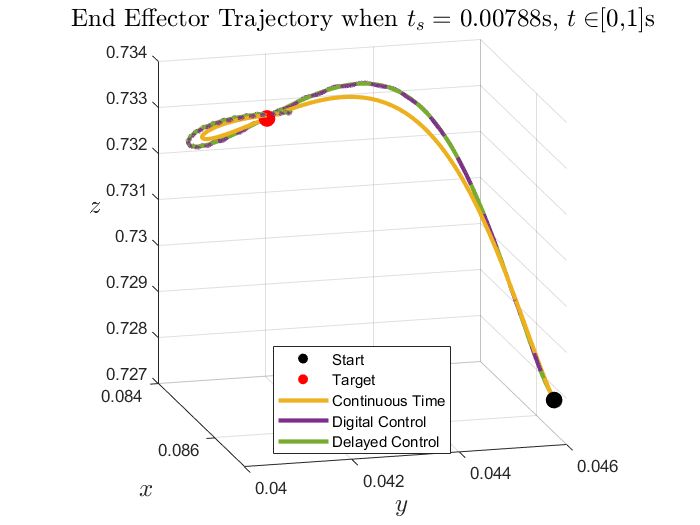

scatter3(EE_Initial(1),EE_Initial(2),EE_Initial(3),100,"black","filled","o")
hold on
scatter3(EE_Target(1),EE_Target(2),EE_Target(3),100,"red","filled","o")
plot3(data.continuous.EE_traj(1,:),data.continuous.EE_traj(2,:),...
    data.continuous.EE_traj(3,:),"LineWidth",2.5);
plot3(data.digital.EE_traj(1,:),data.digital.EE_traj(2,:),...
    data.digital.EE_traj(3,:),"LineWidth",2.5);
plot3(data.delay.EE_traj(1,:),data.delay.EE_traj(2,:), ...
    data.delay.EE_traj(3,:),"LineWidth",2.5);
hold off
title("End Effector Trajectory when $$t_s=$$ "+num2str(data.digital.ts)+ ...
    "s, $$t \in$$[0,"+num2str(SolverOpt.end_time)+"]s", ...
    "FontSize",15,"Interpreter","latex")
view(75,15)
pbaspect([1 1 1])
legend("Start","Target","Continuous Time","Digital Control","Delayed Control","Location","south")
xlabel("$$x$$","Interpreter","latex","FontSize",15)
ylabel("$$y$$","Interpreter","latex","FontSize",15)
zlabel("$$z$$","Interpreter","latex","FontSize",15,"Rotation",pi/2)
grid on

End Effector Error

% 需要对齐采样频率
data.continuous.EE_traj_interp=data.continuous.EE_traj;
writting_data="data.digital";
command="data.digital.EE_traj_interp=[";
for i=1:3
    command=command+"interp1("+writting_data+".duration,"+writting_data+".EE_traj("+...
        num2str(i)+",:),data.continuous.duration,'spline','extrap')';";
end
command=command+"];";
eval(command);
writting_data="data.delay";
command="data.delay.EE_traj_interp=[";
for i=1:3
    command=command+"interp1("+writting_data+".duration,"+writting_data+".EE_traj("+...
        num2str(i)+",:),data.continuous.duration,'spline','extrap')';";
end
command=command+"];";
eval(command);

End Effector Error Visualization

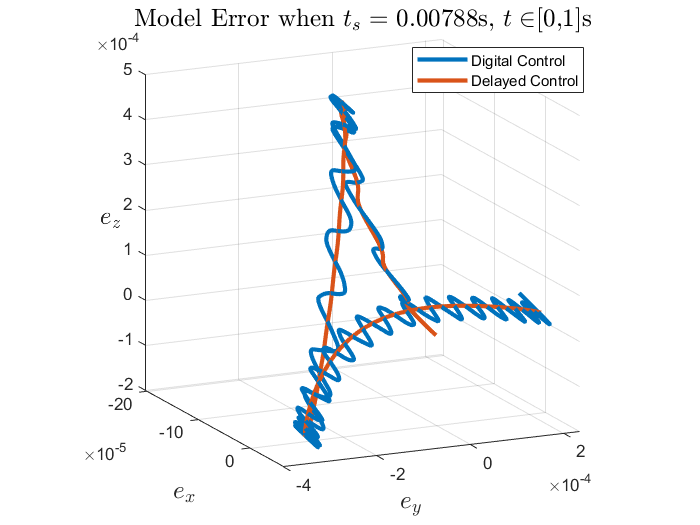

plot3(data.digital.EE_traj_interp(1,:)-data.continuous.EE_traj_interp(1,:), ...
    data.digital.EE_traj_interp(2,:)-data.continuous.EE_traj_interp(2,:), ...
    data.digital.EE_traj_interp(3,:)-data.continuous.EE_traj_interp(3,:),"LineWidth",2.5)
hold on
plot3(data.delay.EE_traj_interp(1,:)-data.continuous.EE_traj_interp(1,:), ...
    data.delay.EE_traj_interp(2,:)-data.continuous.EE_traj_interp(2,:), ...
    data.delay.EE_traj_interp(3,:)-data.continuous.EE_traj_interp(3,:),"LineWidth",2.5)
hold off
pbaspect([1 1 1])
xlabel("$$e_x$$","Interpreter","latex","FontSize",15)
ylabel("$$e_y$$","Interpreter","latex","FontSize",15)
zlabel("$$e_z$$","Interpreter","latex","FontSize",15,"Rotation",pi/2)
legend("Digital Control","Delayed Control","Location","best")
title("Model Error when $$t_s=$$ "+num2str(data.digital.ts)+ ...
    "s, $$t \in$$[0,"+num2str(SolverOpt.end_time)+"]s", ...
    "FontSize",15,"Interpreter","latex")
view(65,15)
grid on

End Effector Error Time History

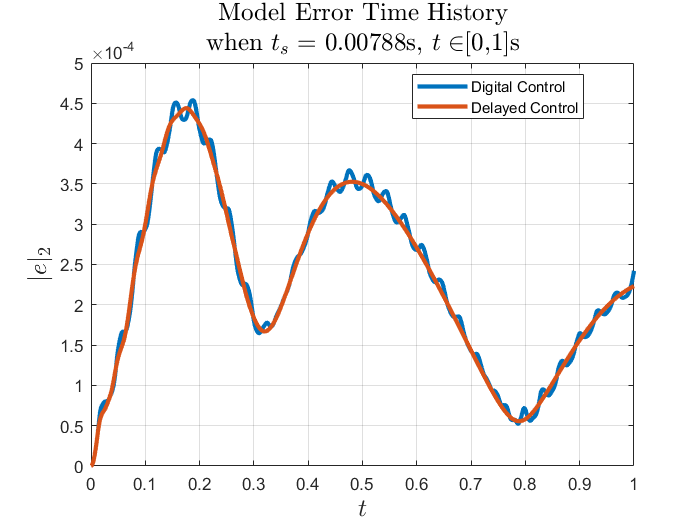

data.digital.EE_error_history=data.continuous.duration;
data.delay.EE_error_history=data.continuous.duration;
for i=1:length(data.continuous.duration)
    data.digital.EE_error_history(i)=norm(data.digital.EE_traj_interp(:,i)-...
        data.continuous.EE_traj_interp(:,i));
    data.delay.EE_error_history(i)=norm(data.delay.EE_traj_interp(:,i)-...
        data.continuous.EE_traj_interp(:,i));
end
plot(data.continuous.duration,data.digital.EE_error_history,"LineWidth",2.5)
hold on
plot(data.continuous.duration,data.delay.EE_error_history,"LineWidth",2.5)
hold off
title(["Model Error Time History";"when $$t_s=$$ "+num2str(data.digital.ts)+ ...
    "s, $$t \in$$[0,"+num2str(SolverOpt.end_time)+"]s"], ...
    "FontSize",15,"Interpreter","latex")
legend("Digital Control","Delayed Control","Location","best")
xlabel("$$t$$","Interpreter","latex","FontSize",15)
ylabel("$$|e|_2$$","Interpreter","latex","FontSize",15)
grid on

Save Data

filename="Data\Comparison_"+datestr(now,"yyyy_mm_dd")+".mat";
save(filename,'data')